## Differential equations in Matlab (PSYC 9015 Topic 3). 

This liveScript accompanies class materials for Topic 3. These exercises use Matlab's Symbolic Toolbox. Please see [this resource](https://www.mathworks.com/help/symbolic/computational-mathematics-in-symbolic-math-toolbox.html) for an excellent introduction to this toolbox.

**Exercise 1a: **Use the MATLAB function *ExponentialGrowth.m* to examine what happens for a = .1, .5, 1, 1.5.

processing... ... ...


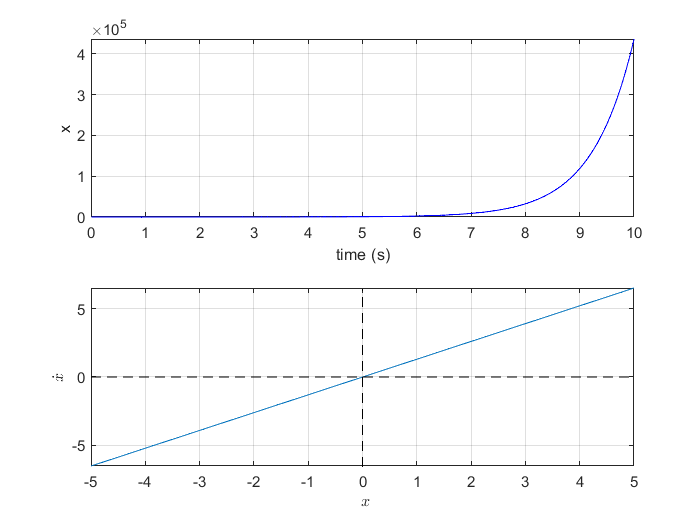

t =     0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900
    0.1000


x = 	1.0e+05 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


[t, x] = ExponentialGrowth(1,1.3,10)

**Exercise 2a: **Use the MATLAB function *LogisticGrowth.m* to examine what happens for different values of α> 0 and β> 0.

processing... ... ...


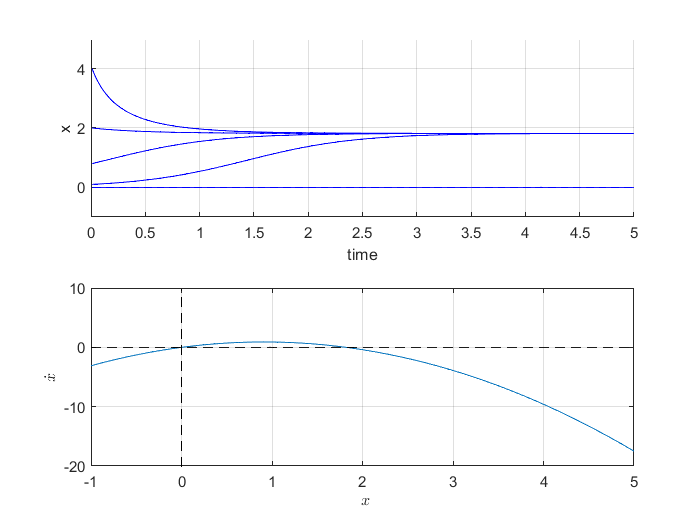

[t x] = LogisticGrowth([0 .1 .8 2 4],2,1.1,5);

**Exercise 3. **Use MATLAB to plot the following functions. 

syms f(x)
a = 2

a = 2

b = 1

b = 1

f(x) = b-a*x;

figure
fplot(f(x))
hold

Current plot held


fplot(0)
xlabel('x')
ylabel('dx/dt')
grid on


syms f(x)
a = 0

a = 0

b = 1.1

b = 1.1000

f(x) = a*x-b*x^2

$$f(x) = -\frac{11\,x^{2}}{10}$$

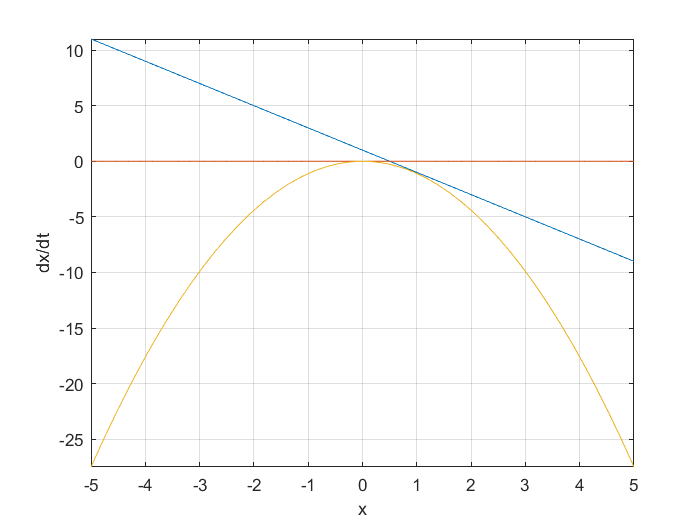

Current plot released



fplot(f(x),[-5,5])
hold

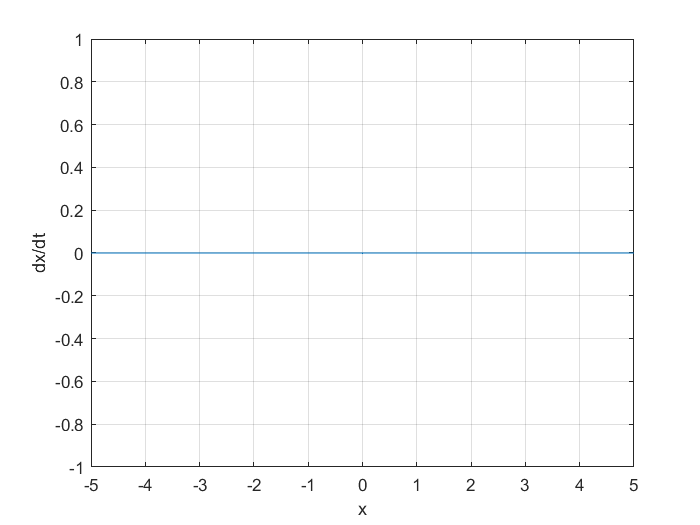

fplot(0)
xlabel('x')
ylabel('dx/dt')
grid on



syms f(x)
a = 1

a = 1

b = 1

b = 1

f(x) = -a*sin(x)-2*b*sin(2*x)

$$f(x) = -2\,\sin\left(2\,x\right)-\sin\left(x\right)$$


fplot(f(x))
hold

Current plot held


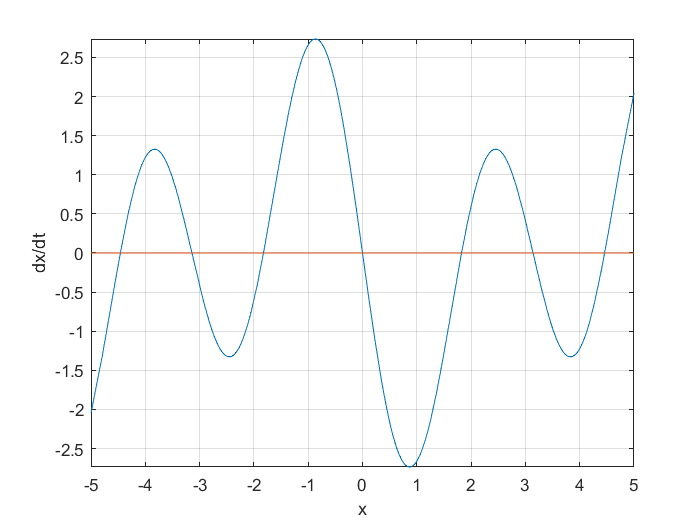

fplot(0)
xlabel('x')
ylabel('dx/dt')
grid on

**Exercise 5. **Use the ‘ode45’ function to numerically integrate the below ODEs. IntMyODE_eq1 should be in your Matlab path.

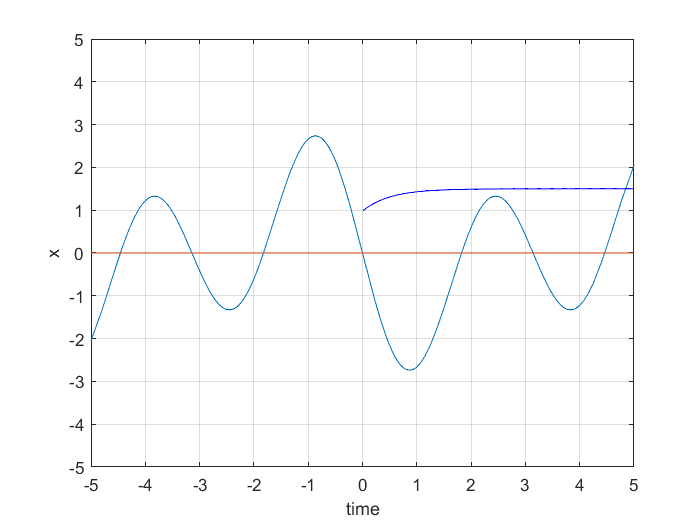

IntMyODE_eq1(1 ,5)

**Exercise 6A. **Use the ‘*_sf’ functions in MATLAB to explore the vector fields for the below systems using different parameters.

processing... ... ...


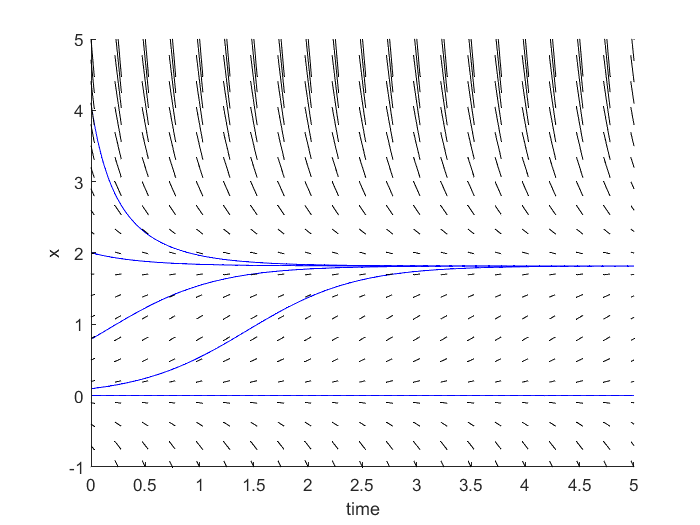

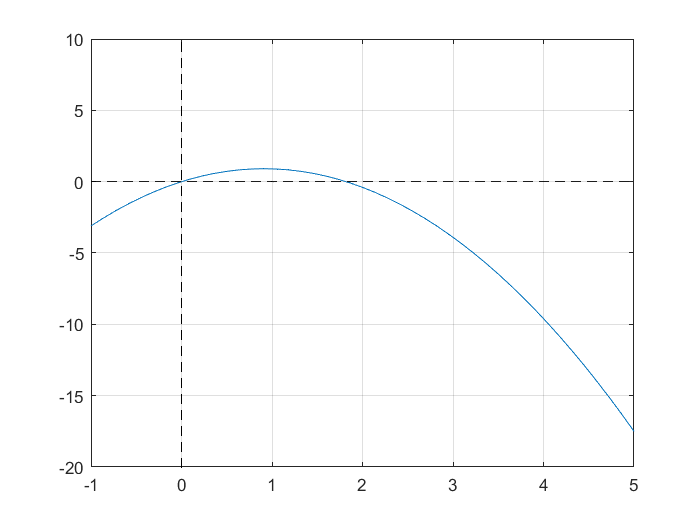

[t x] = LogisticGrowth_sf([0 .1 .8 2 4],2,1.1,5);

**Exercise 6B. **Create vector fields for the below systems using different parameters.

Simple sine model

dt = .2

dt = 0.2000

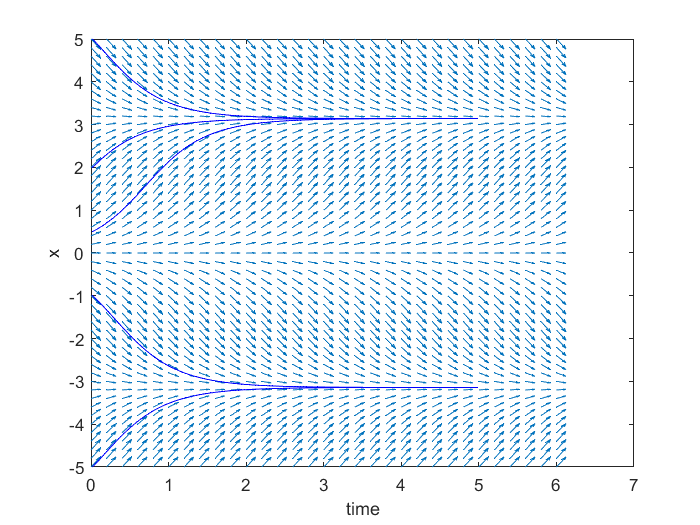

[X,Y] = meshgrid(0:dt:6,-5:dt:5);

% define vector x and y components (U and V, respectively)
U = ones(size(X))*dt; % horizontal component (time)
V = (2*sin(Y)).*dt; % vertical component (change in state; given by f(x)*dt

figure
quiver(X,Y,U,V,1)
xlabel('Time (s)')
ylabel('x')

% plot the ODE solutions from different initial conditions
hold on
IntMyODE_sin(.5,2, 5)
IntMyODE_sin(2,2, 5)
IntMyODE_sin(5,2, 5)
IntMyODE_sin(-1,2, 5)
IntMyODE_sin(-5,2, 5)

HKB model

dt = .2

dt = 0.2000

[X,Y] = meshgrid(0:dt:6,-5:dt:5);

U = ones(size(X))*dt;
V = (-1*sin(Y)-2*0.5*sin(2*Y)).*dt;

figure
quiver(X,Y,U,V,1)
xlabel('Time (s)')
ylabel('x')

% plot the ODE solutions from different initial conditions
hold

Current plot held


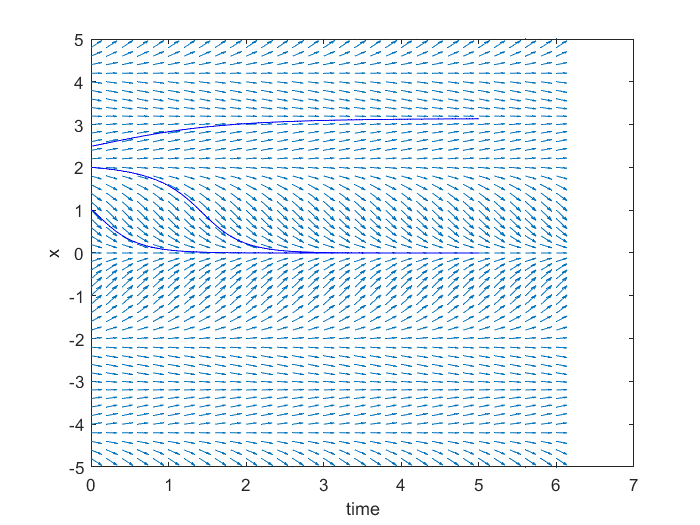

IntMyODE_HKB(1,1,0.5,5);
IntMyODE_HKB(2,1,0.5,5);
IntMyODE_HKB(2.5,1,0.5,5);

***Exercise 7-9. ***Use the diff functions in MATLAB to find the stability of the fixed points for the following systems.

syms f(x)
f(x) = 2*x^2-8

$$f(x) = 2\,x^{2}-8$$


figure
fplot(f(x))
hold

Current plot held


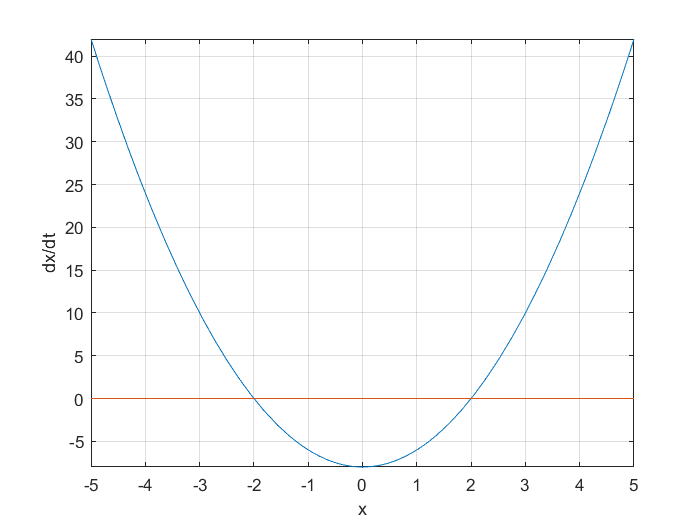

fplot(0)
xlabel('x')
ylabel('dx/dt')
grid on


% Find derivative of f(x) - rate of change of this fuction - slope of f(x)
fd(x) = diff(f(x));

% Find the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==0);

% Convert fixed points from symbolic to numeric variable for plotting
fp_num = double(fp);

% substitue the values of the fixed points into the derivative function to
% get the slope of f(x) at the fixed points
m = subs(fd(fp_num));
m_num = double(m)

m_num =     -8
     8



% Classify fixed points
stable_fp = m_num<0;
unstable_fp = m_num>0;

% Plot the function and the fixed points
figure
fplot(f(x))
hold

Current plot held


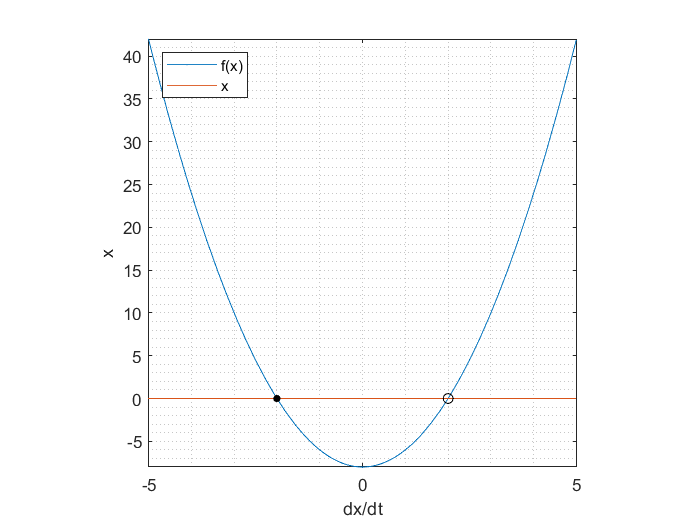

fplot(0)

% Next line plots the location of the fixed point as (x,y) coordinate. x = fp value, y = f(fp)
plot(fp_num(unstable_fp),f(fp_num(unstable_fp)),'ok') % Unstable fixed points
plot(fp_num(stable_fp),f(fp_num(stable_fp)),'.k','markersize',15) % Stable fixed points

grid minor
axis square
ylabel('x')
xlabel('dx/dt')
legend('f(x)','x','Location','Northwest')